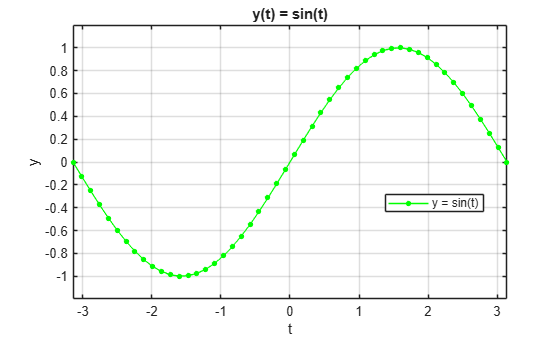

clear; clc; close all;

% 1 UZDUOTIS
t = linspace(-pi, pi, 50);
y = sin(t);

figure(1);
plot(t, y, 'g.-', 'MarkerSize', 12);   
axis([min(t) max(t) min(y)-0.2 max(y)+0.2]);
title('y(t) = sin(t)');
xlabel('t');
ylabel('y');
legend('y = sin(t)', 'Location', 'best');
grid on;

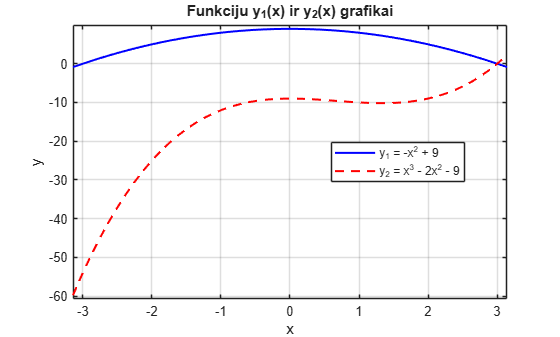



x  = linspace(-pi, pi, 50);
y1 = -x.^2 + 9;
y2 = x.^3 - 2*x.^2 - 9;

figure(2);
plot(x, y1, 'b-', x, y2, 'r--', 'LineWidth', 1.5);


ymin = min([y1 y2]);
ymax = max([y1 y2]);
axis([min(x) max(x) ymin-1 ymax+1]);
title('Funkciju y_1(x) ir y_2(x) grafikai');
xlabel('x');
ylabel('y');
legend('y_1 = -x^2 + 9', 'y_2 = x^3 - 2x^2 - 9', 'Location', 'best');
grid on;

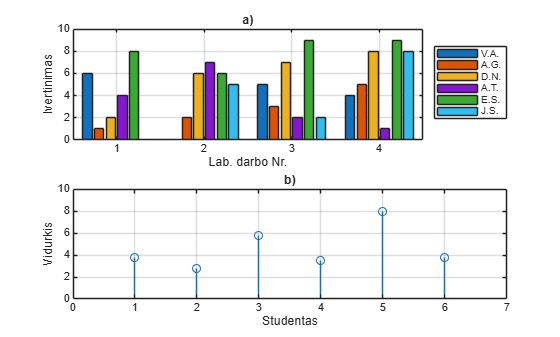


%2 UZDUOTIS


vardai = {'V.A.', 'A.G.', 'D.N.', 'A.T.', 'E.S.', 'J.S.'};
P = [6 0 5 4;
     1 2 3 5;
     2 6 7 8;
     4 7 2 1;
     8 6 9 9;
     0 5 2 8];         
figure(3);
subplot(2, 1, 1);
bar(P');                       
axis([0.5 4.5 0 10]);
set(gca, 'XTick', 1:4);
title('a)');
xlabel('Lab. darbo Nr.');
ylabel('Ivertinimas');
legend(vardai, 'Location', 'eastoutside');
grid on;

vidurkis = mean(P, 2);

subplot(2, 1, 2);
stem(1:6, vidurkis, 'o');
axis([0 7 0 10]);
title('b)');
xlabel('Studentas');
ylabel('Vidurkis');
grid on;


vidurkis_lab = mean(P, 1);
disp('Vidurkis pagal lab. darbus:'); disp(vidurkis_lab);

Vidurkis pagal lab. darbus:
    3.5000    4.3333    4.6667    5.8333



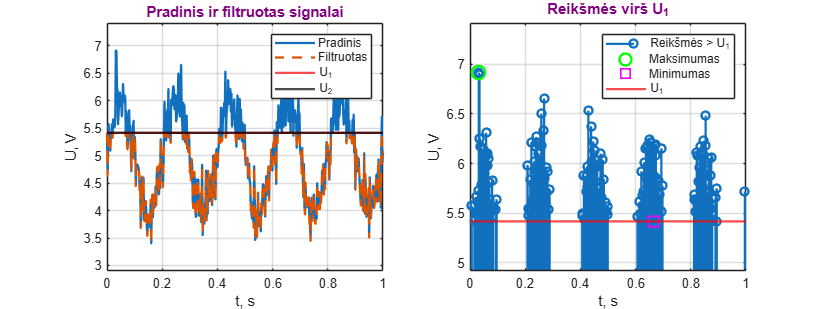


% PAPILDOMA


t = linspace(0, 1, 500);
u = 5 + sin(2*pi*5*t) + 0.3*randn(size(t));   
U1 = 5.4172;                                  
U2 = 5.4172;
uf = u;                                       
uf(u > U1) = U1;                              

violet = [0.5 0 0.5];

figure('Position', [100 200 1200 450]);


subplot(1, 2, 1);
plot(t, u, '-', 'LineWidth', 1.75); hold on;
plot(t, uf, '--', 'LineWidth', 1.75);
yline(U1, 'r', 'LineWidth', 1.75);
yline(U2, 'k', 'LineWidth', 1.75);
axis([min(t) max(t) min(u)-0.5 max(u)+0.5]);
title('Pradinis ir filtruotas signalai', 'Color', violet, 'FontSize', 11);
xlabel('t, s'); ylabel('U, V');
legend('Pradinis', 'Filtruotas', 'U_1', 'U_2');
grid on;

idx = u > U1;
ta = t(idx);
ua = u(idx);

[umax, imax] = max(ua);
[umin, imin] = min(ua);

subplot(1, 2, 2);
stem(ta, ua, 'LineWidth', 1.75); hold on;
plot(ta(imax), umax, 'o', 'Color', 'g', 'LineWidth', 1.75, 'MarkerSize', 10);
plot(ta(imin), umin, 's', 'Color', 'm', 'LineWidth', 1.75, 'MarkerSize', 10);
yline(U1, 'r', 'LineWidth', 1.75);
axis([min(t) max(t) U1-0.5 umax+0.5]);
title('Reikšmės virš U_1', 'Color', violet, 'FontSize', 11);
xlabel('t, s'); ylabel('U, V');
legend('Reikšmės > U_1', 'Maksimumas', 'Minimumas', 'U_1');
grid on;